# Simulación de un dipolo en caida libre por un tubo de cobre

- Jeanette Arjona Hernández/ICT - A01236226

- Sebastián Reséndiz García/INA - A01236336

- José Alfonso López Blanco/Lic- A01236245

- Arif Morán Velázquez/IFI- A01234442

- Alan Martínez Varela/ICT - A01236407

clc
clear all

%%Constantes
miu0=4*pi*(10^-7);
om=59.6*10^6; %Conductividad del cobre
ro=1.72e-08; %Conductividad del cobre
a=-9.81; %Aceleracion por la gravedad


%%Datos del Iman
h2=0.3 %Altura sobre el tubo

h2 = 0.3000

anchom=0.007 %ancho del iman

anchom = 0.0070

largom=0.005 

largom = 0.0050

sizem=0.0385 %Largo del iman

sizem = 0.0385

B=0.01 %Teslas

B = 0.0100

miu1=(2*pi*B*0.001^2)/miu0;
m=0.005 %Masa del iman Kg

m = 0.0050


%%%Tubo
d=0.015; %Diamtetro del tubo
r=d/2; %Radio interior del tubo 
h = 1 %altura del tubo

h = 1

g=0.0005 %Grosor 2 mm

g = 5.0000e-04

Loops=sizem/g %h/g;

Loops = 77

R=log((r+g)/(r))/(2*pi*h*om);
c=1/R;
%R=(ro*2*pi*r*Loops)/(pi*(g/2)^2)


%Tiempo
dt=0.01; %Diferencial de tiempo
tl=3;
t=0:dt:tl;

%%%%%%%%%%espira
pitch = 0.02;
syms th
x = r*sin(th);
y = r*cos(th);
z1 = th/(2*pi)*pitch;
tmax = 2*pi*h/pitch;

%Vectores  de posicion,velocidad y aceleracion
Pm=zeros(1,length(t));
Pm(1)=h+h2; %Posicion Inicial

a1=zeros(1,length(t));
a1(1)=a;

v=zeros(1,length(t));
v(1)=0;

%Caida libre
for i=1:(length(t)-1)
    Pm(i+1)=Pm(i)+v(i)*dt+(a1(i)*dt^2)/2;
    v(i+1)=v(i)+a1(1)*dt;
    a1(i+1)=a;
    if Pm(i+1)<=h
        break
    end
end
%%%%%%%%%%%%%Movimiento en la espira%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
p=i;
%km=9*(miu0^2)*(miu1^2)*(r^4)*(Loops^2)/(4*R*m)
%f=@(z,v)-9.81-(km*(z.^2)/((z.^2+r^2).^5)).*v; % Presentacion
f=@(z,v)-9.81-((15/1024)*(miu0^2)*(miu1^2)*c*(1/(r^3)-1/(r+g)^3))*v/m

f = function_handle with value:
    @(z,v)-9.81-((15/1024)*(miu0^2)*(miu1^2)*c*(1/(r^3)-1/(r+g)^3))*v/m


%f=@(z,v)-9.81+(0.2/80)*v^2% Paracaidas
%f=@(z,v)-9.81-(((Loops^2)*3*(miu1^2)*(miu0^2)*(r^4))/(4*R*m))*((7*(z^2)-(r^2))/((z^2)+(r^2))^5)*v;%Solucuion
%obtenida
%f=@(z,v)-9.81-((2*(Loops^2)*3*(miu1^2)*(miu0^2)*r^4)/(2*R*h*m))*((4*z^2-r^2)/(z^2+r^2)^(7/2))*v
%teorema de existencia y unicidad
dydt=@(y)[y(2); f(y(1),y(2))]

dydt = function_handle with value:
    @(y)[y(2);f(y(1),y(2))]


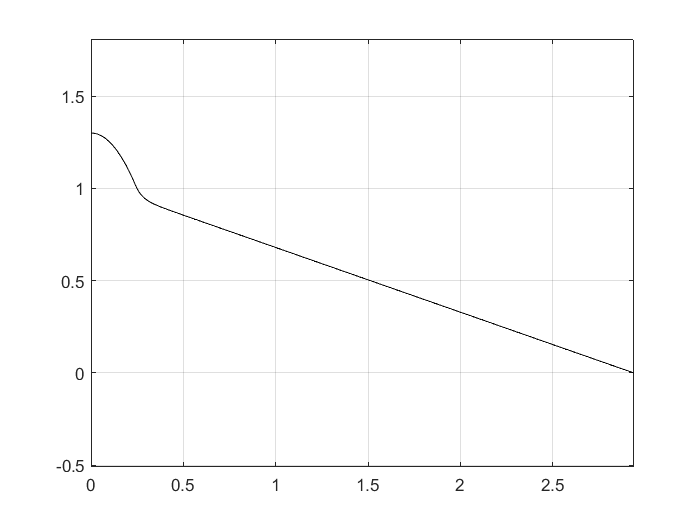

for i5=p:length(t)-1
    z0=[Pm(i5);v(i5)];
    k1=dydt(z0);
    k2=dydt(z0+(dt*k1)/2);
    k3=dydt(z0+(dt*k2)/2);
    k4=dydt(z0+dt*k3);
    
    Pm(i5+1)=Pm(i5)+(dt/6)*(k1(1)+2*k2(1)+2*k3(1)+k4(1));
    v(i5+1)=v(i5)+(dt/6)*(k1(2)+2*k2(2)+2*k3(2)+k4(2));
    a1(i5+1)=f(Pm(i5),v(i5));
    if Pm(i5+1)<=0
        break
    end
end
 plot(t(1:i5+1),Pm(1:i5+1),'k')
 grid on
 axis equal

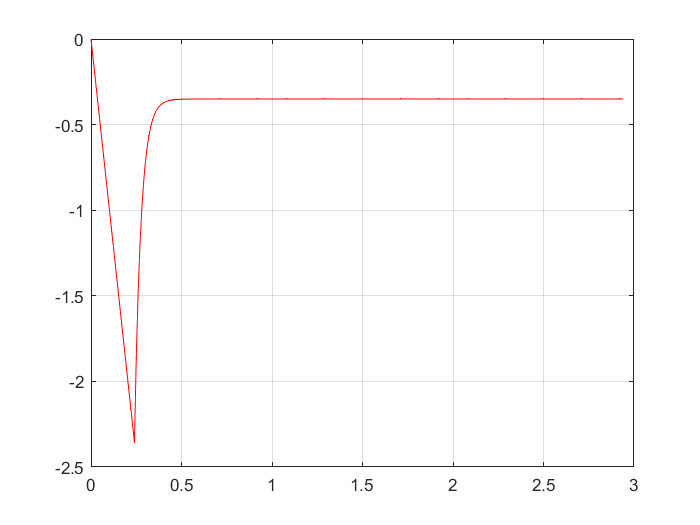

 plot(t(1:i5+1),v(1:i5+1),'r')
grid on

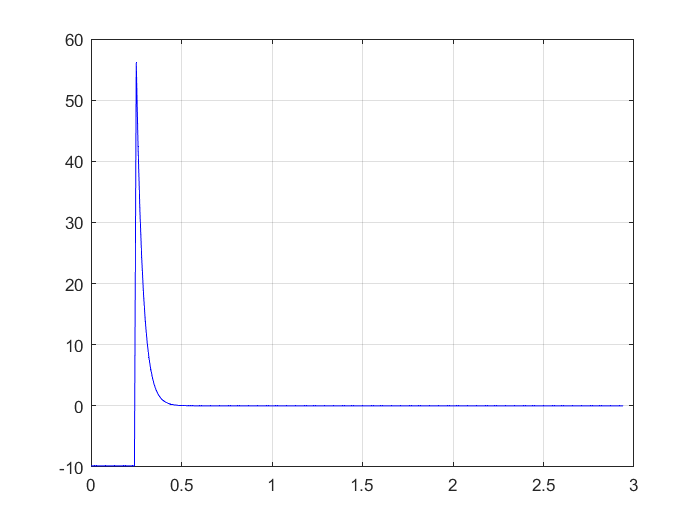

 plot(t(1:i5+1),a1(1:i5+1),'b')
 grid on

 gg=0

gg = 0

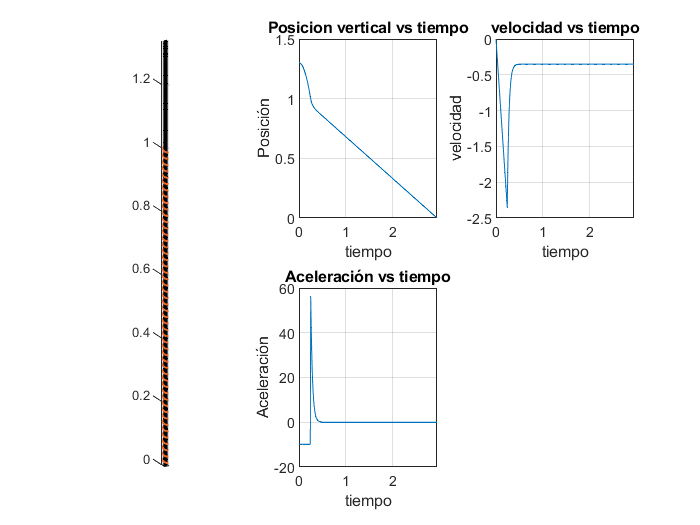

% [ty,y] = ode45(dydt,[0 tl],[Pm(26); v(26)]);
% z=y(:,1)
% plot(ty,z,'r')
% grid on
% plot(ty,y(:,2))
% grid on
% axis equal

% for i2=p:length(t)-1 
%     l1=dt*f(Pm(i2),v(i2));
%         k1=dt*(v(i2)); 
%     l2=dt*f(Pm(i2)+k1/2,v(i2)+l1/2);
%         k2=dt*(v(i2)+l1/2);
%     l3=dt*f(Pm(i2)+k2/2,v(i2)+l2/2);
%         k3=dt*(v(i2)+l2/2);
%     l4=dt*f(Pm(i2)+k3,v(i2)+l3);
%         k4=dt*(v(i2)+l3);
%         
%         Pm(i2+1)=Pm(i2)+(1/6)*(k1+2*k2+2*k3+k4);
%         a1(i2+1)=f(Pm(i2),v(i2));
%         v(i2+1)=v(i2)+(1/6)*(l1+2*l2+2*l3+l4);
%         
%     if Pm(i2+1)<=0
%           Pm(i2+1)=0;
%          break
%     end 
% end

%%%%Parte del solenoide
subplot(2,3,[1,4])
fplot3(x, y, z1, [0 tmax],'color',[0.9100    0.4100    0.1700],'LineWidth', 1)
axis equal
hold on
%%%%%%%%%%%%%Iman%%%%%%%%%%
P = [0,0,h+h2+sizem/2] ;   % you center point 
L = [anchom,largom,sizem] ;  % your cube dimensions 
O = P-L/2 ;       % Get the origin of cube so that P is at center 
plotcube(L,O,1,[1 0 0]);   % use function plotcube 
% plot3(0,0,Pm(1),'k.','MarkerSize',1);%Pinicial

for i3=1:length(t)
    P = [0,0,Pm(i3)+sizem/2];   % you center point
    L = [anchom,largom,sizem] ;  % your cube dimensions 
    O = P-L/2 ;
    plotcube(L,O,1,[0 0 0])
    plot3(0,0,Pm(i3),'k')
    pause(0.1)
end
plot3(0,0,Pm,'k.',"MarkerSize",1);%Trayectoria
hold off


subplot(2,3,2)%Posicion vertical vs tiempo
plot(t(1:i5+1),Pm(1:i5+1))
grid on
title('Posicion vertical vs tiempo')
xlabel('tiempo')
ylabel('Posición')


subplot(2,3,3)%Velocidad vs tiempo
plot(t(1:i5+1),v(1:i5+1))
grid on
title('velocidad vs tiempo')
xlabel('tiempo')
ylabel('velocidad')

subplot(2,3,5)%Aceleracion vs tiempo
plot(t(1:i5+1),a1(1:i5+1))
grid on
title('Aceleración vs tiempo')
xlabel('tiempo')
ylabel('Aceleración')


% subplot(2,3,6)%Fuerza neta vs tiempo
% plot(t,Emf)
% grid on
% title('Voltaje vs tiempo')
% xlabel('tiempo')
% ylabel('Fuerza neta')




